# MATH-370 Final Exam 

## Amelia Rotondo - 887925113 

warning off;

#### Problem 4: Linear & NonLinear Data Fits

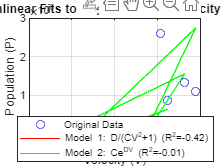

% Initial Data:
P = [341948, 1092759, 5491, 49375, 1340000, 365, 2500, 78200, 867023, 14000, 23700, 70700, 304500, 138000, 2602000];
V = [4.81, 5.88, 3.31, 4.90, 5.62, 2.76, 2.27, 3.85, 5.21, 3.70, 3.27, 4.31, 4.42, 4.39, 5.05];

% === Model 1: P = D / (CV^2 + 1) ================

% Nonlinear regression for Model 1
modelFunc1 = @(b, V) b(2) ./ (b(1)*V.^2 + 1);
initialGuess1 = [1, 1];
options = optimset('Display','off');
b1 = lsqcurvefit(modelFunc1, initialGuess1, V, P, [], [], options);
C1 = b1(1);
D1 = b1(2);
P_fit_1 = modelFunc1(b1, V);
Rsq1 = myRsq(P, P_fit_1);

% === Model 2: P = Ce^(DV) ====================

% Linear regression for Model 2
ln_P = log(P);
X = [V' ones(length(V), 1)];
b = X \ ln_P';  
D = b(1);
C = exp(b(2));
P_fit_2 = C * exp(D * V);
Rsq2 = myRsq(P, P_fit_2);

% === Plotting ====================

% Plotting the original data
figure;
plot(V, P, 'bo', 'DisplayName', 'Original Data');
hold on;

% Plotting Model 1 Fit
plot(V, P_fit_1, 'r-', 'DisplayName', sprintf('Model 1: D/(CV^2+1) (R^2=%.2f)', Rsq1));

% Plotting Model 2 Fit
plot(V, P_fit_2, 'g-', 'DisplayName', sprintf('Model 2: Ce^{DV} (R^2=%.2f)', Rsq2));

% Labels and Legend
xlabel('Velocity (V)');
ylabel('Population (P)');
title('Nonlinear Fits to Population and Velocity Data');
legend('show');
grid on;
hold off;

#### Problem 5: Asprin Drug-Dosage Problem

% C(t) = C0 * e^(-k*t)

Part 5-B:

% k = 0.075 per Hour 
% dosage produces 2.5 mg/dl concentration 
% What is the Highest Concentration in the body?

Part 5-C:

% How Many Days til:
% Concentration reachest 90% of Highest Level?

#### Problem 6: ODE Solution & Euler Approximation

% dudt = (3 - u)*(1 - u)^2 

Part 6-A: 

% Part 6-A: Find Equilibria
syms u
eqn = (3 - u)*(1 - u)^2 == 0;
equilibria = double(solve(eqn, u));
disp('Equilibrium points:');

Equilibrium points:


disp(equilibria);

     1
     1
     3



Part 6-B: 

% Part 6-B: Determine Stability of Equilibria
dudt = @(t, u) (3 - u) * (1 - u)^2;

% Determine Critical Values
dudt_prime = matlabFunction(diff(dudt(1, u), u));

% Derive Stable Points from Equilibria 
stability = arrayfun(dudt_prime, equilibria);
disp('Stability at equilibrium points:');

Stability at equilibrium points:


disp(stability);

     0
     0
    -4



Part 6-C: 

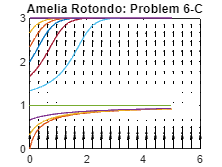

% Part 6-C: Draw Solution Trajectories in Phase Space 
tspan = [0, 5];
y0_values = linspace(0, 3, 10); 

% Create a grid for quiver plot
[t_grid, u_grid] = meshgrid(linspace(0, 6, 20), linspace(0, 3, 15));
du_grid = (3 - u_grid) .* (1 - u_grid).^2; 

% Plotting the quiver plot
figure;
quiver(t_grid, u_grid, zeros(size(du_grid)), du_grid, 'k', 'MaxHeadSize', 0.6);
hold on;

% Plotting solution trajectories
for y0 = y0_values
    [T, Y] = ode45(dudt, tspan, y0);
    plot(T, Y);
end
title('Amelia Rotondo: Problem 6-C');
hold off;

Part 6-D:  

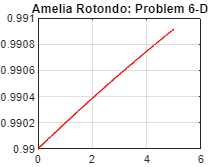

% Part 6-D: Euler Method Approximation
deltaT = 0.1;
tspan = [0, 5];
y0 = 0.99;

[t, y] = myEuler(dudt, tspan, y0, deltaT);

% Plotting Euler approximation
figure;
plot(t, y, 'r-');
title('Amelia Rotondo: Problem 6-D');
grid on;

#### Problem 7: ODE Solutions 

Part 7-A: 

% System of Autonomous Differential Equations
% dx/dt = (4 - y) * x 
% dy/dt = (3 - 2x) * y

% Finding Equilibrium Points ( dx/dt = dy/dt = 0 )
syms x y
eq1 = (4 - y) * x == 0;
eq2 = (3 - 2 * x) * y == 0;
sol = solve([eq1, eq2], [x, y]);

% Display Equilibrium Points
equ_pts = [double(sol.x), double(sol.y)];
disp('Equilibrium Points:');

Equilibrium Points:


disp(equ_pts);

         0         0
    1.5000    4.0000



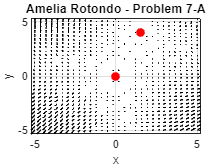


% Define the RHS of the system
rhs = @(t, y) [(4 - y(2)) * y(1); (3 - 2 * y(1)) * y(2)];

% Phase Space Grid Around Equilibrium Points
Np = 30; 
[x_grid, y_grid] = meshgrid(linspace(-5, 5, Np), linspace(-5, 5, Np));
dx = (4 - y_grid) .* x_grid;
dy = (3 - 2 .* x_grid) .* y_grid;

% Plotting Phase Portrait
figure;
quiver(x_grid, y_grid, dx, dy, 'k', 'MaxHeadSize', 0.6);
hold on;
plot(equ_pts(:,1), equ_pts(:,2), 'ro', 'MarkerFaceColor', 'r');
title('Amelia Rotondo - Problem 7-A');
xlabel('x');
ylabel('y');
grid on;
hold off;

Part 7-B:

% dxdt = (4 - y)*x
% dydt = (-3 + 2x)*y 

% Finding Equilibrium Points ( dx/dt = dy/dt = 0 )
syms x y
eq1 = (4 - y) * x == 0;
eq2 = (-3 + 2 * x) * y == 0;
sol = solve([eq1, eq2], [x, y]);

% Display Equilibrium Points
equ_pts = [double(sol.x), double(sol.y)];
disp('Equilibrium Points:');

Equilibrium Points:


disp(equ_pts);

         0         0
    1.5000    4.0000



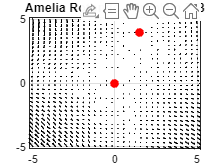


% Phase Space Grid Around Equilibrium Points
Np = 30; 
[x_grid, y_grid] = meshgrid(linspace(-5, 5, Np), linspace(-5, 5, Np));
dx = (4 - y_grid) .* x_grid;
dy = (-3 + 2 .* x_grid) .* y_grid;

% Plotting Phase Portrait
figure;
quiver(x_grid, y_grid, dx, dy, 'k', 'MaxHeadSize', 0.6);
hold on;
plot(equ_pts(:,1), equ_pts(:,2), 'ro', 'MarkerFaceColor', 'r');
title('Amelia Rotondo - Problem 7-B');
grid on;
hold off;